# 2.3.1 `采样定理 `

## $\mathrm{e1}\left(t\right)=\mathrm{sin}\left(2\pi t\right)$、$\mathrm{e2}\left(t\right)=\mathrm{sin}\left(18\pi t+180°\right)$、$\mathrm{e3}\left(t\right)=\mathrm{sin}\left(22\pi t\right)$

## `三种连续时间信号，用采样频率 10Hz 进行周期采样，试用 MATLAB 画出 t=0 `

## `到 1 秒的采样信号。分析发生了什么现象及原因？ `

## `画出所有连续时间信号。 `

## `如果采样周期变为 20Hz、30Hz 时，重复完成上述要求，``并从频域解释产生 `

## `上述现象的原因，定性分析，也可通过画出信号的频谱进行分析``。`

## `·对e1、e2、e3用采样频率10Hz进行周期采样，画出t=0~1的采样信号（离散)`

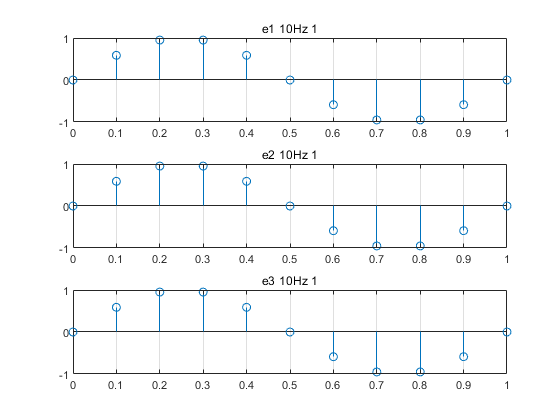

%e1 10Hz 
f=1;fs=10;  %f信号频率，fs信号采样频率
t=0:1/fs:1;
e1=sin(2*pi*f*t);
subplot(3,1,1);
stem(t,e1);grid on 
title('e1 10Hz 1');


%e2 10Hz 
f=9;fs=10;
t=0:1/fs:1;
e2=sin(2*pi*f*t+pi);
subplot(3,1,2);
stem(t,e2);grid on
title('e2 10Hz 1');


%e3 10Hz 
f=11;fs=10;
t=0:1/fs:1;
e3=sin(2*pi*f*t);
subplot(3,1,3);
stem(t,e3);grid on
title('e3 10Hz 1');

## **·对e1、e2、e3用采样频率20Hz进行周期采样，画出t=0~1的采样信号（离散）**

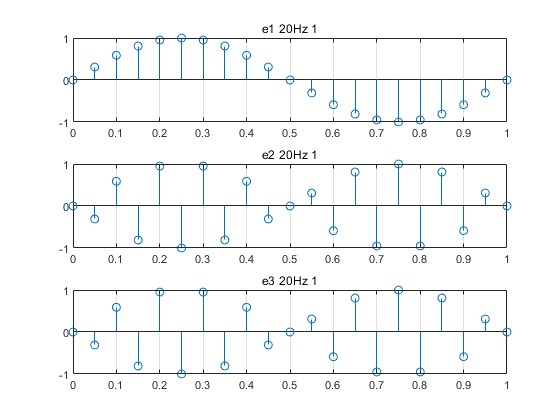


%e1 20Hz 
figure(2);
f=1;fs=20;
t=0:1/fs:1;
e1=sin(2*pi*f*t);
subplot(3,1,1);
stem(t,e1);grid on
title('e1 20Hz 1');


%e2 20Hz 
f=9;fs=20;
t=0:1/fs:1;
e2=sin(2*pi*f*t+pi);
subplot(3,1,2);
stem(t,e2);grid on
title('e2 20Hz 1');


%e3 20Hz 
f=11;fs=20;
t=0:1/fs:1;
e3=sin(2*pi*f*t);
subplot(3,1,3);
stem(t,e3);grid on
title('e3 20Hz 1');

## **·对e1、e2、e3用采样频率30Hz进行周期采样，画出t=0~1的采样信号（离散）**

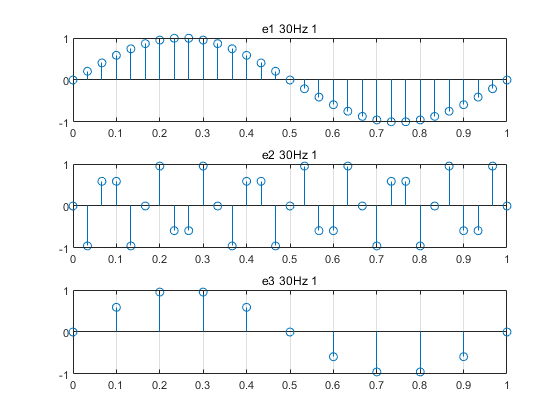

%e1 30Hz 
figure(3);
f=1;fs=30;
t=0:1/fs:1;
e1=sin(2*pi*f*t);
subplot(3,1,1);
stem(t,e1);grid on
title('e1 30Hz 1');

%e2 30Hz 
f=9;fs=30;
t=0:1/fs:1;
e2=sin(2*pi*f*t+pi);
subplot(3,1,2);
stem(t,e2);grid on
title('e2 30Hz 1');


%e3 30Hz 
f=11;fs=10;
t=0:1/fs:1;
e3=sin(2*pi*f*t);
subplot(3,1,3);
stem(t,e3);grid on
title('e3 30Hz 1');

## ·对e1、e2、e3用200Hz进行采样以得到比较接近的连续函数

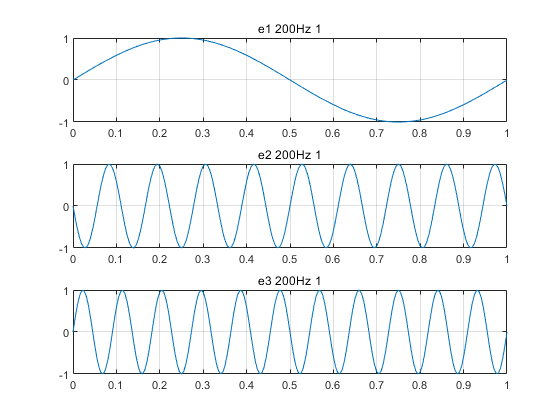

%e1 200Hz 
figure(4);
f=1;fs=200;
t=0:1/fs:1;
e1=sin(2*pi*f*t);
subplot(3,1,1);
plot(t,e1);grid on
title('e1 200Hz 1');

%e2 200Hz 
f=9;fs=200;
t=0:1/fs:1;
e2=sin(2*pi*f*t+pi);
subplot(3,1,2);
plot(t,e2);grid on
title('e2 200Hz 1');


%e3 200Hz 
f=11;fs=200;
t=0:1/fs:1;
e3=sin(2*pi*f*t);
subplot(3,1,3);
plot(t,e3);grid on
title('e3 200Hz 1');

# ·理论依据

## 采样定理：在进行模拟/数字信号的转换过程中，当[采样频率](https://baike.baidu.com/item/%E9%87%87%E6%A0%B7%E9%A2%91%E7%8E%87)fs.max大于信号中最高频率fmax的2倍时(fs.max>2fmax)，采样之后的数字信号完整地保留了原始信号中的信息，一般实际应用中保证采样频率为信号最高频率的2.56～4倍；采样定理又称[奈奎斯特定理](https://baike.baidu.com/item/%E5%A5%88%E5%A5%8E%E6%96%AF%E7%89%B9%E5%AE%9A%E7%90%86)。

# ·现象及结论

## 对比200Hz采样得到的连续信号图像来看

## 对于e1，三种采样信号都能满足对于还原度的要求，因此在三种采样频率下，e1的离散信号都与连续信号相差无几；

## 对于e2，10Hz的采样频率与连续信号相差较多，通过采样定理也可得出10<2*9,20Hz略大于2*9,30Hz采样频率则能够比较好的还原信号图像；

## 对于e3,10Hz和20Hz都不能满足采样信号的要求，30Hz略大于2*11，因此勉强满足信号采样频率要求。

## 结论：根据采样定理，采样频率需要大于信号最高频率两倍，而采样频率越高，对原始信号的还原度越好。